# *Are We Getting Bigger?*

The file `waistmeasure.mat` contains the waist circumference measurement (in cm) for about 8000 individuals in 1999 (first column) and 2009 (second column).

% To see two plot answers, rutn this section.
openfig('GettingBigger1.fig','visible');
openfig('GettingBigger2.fig','visible');

## 1. Load data

Load the dat i the file `waistmeasure.mat`.

load("waistmeasure.mat")

## 2. Create histograms

Create a histogram of the 1999 data. Use the `histogram` function and bin centers in 1 cm integer increments by setting the `BinMethod` property to `integers`.

figure("Name","fig1");
histogram(waist(:,1),"BinMethod","integers")
xlabel("Waist Circumference[cm]")
ylabel("Number of individuals")

Add a similar histogram of the 2009 data on the same axes.

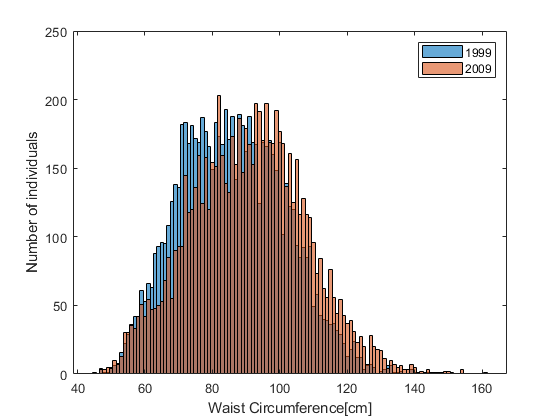

hold on
histogram(waist(:,2),"BinMethod","integers")
legend("1999","2009")
hold off

## 3. Calculate means and standard deviations

Calculate the mean and standard deviation for both years.

mean_1999 = mean(waist(:,1))

mean_1999 = 85.9192

mean_2009 = mean(waist(:,2))

mean_2009 = 90.4684

std_1999 = std(waist(:,1))

std_1999 = 15.5576

std_2009 = std(waist(:,2))

std_2009 = 16.9444

## 4. Calculate theoretical distributions

Calculate the theoretical probability distribution for each year (1999 and 2009) using the formula


$$p\left(w\right)=\;\frac{1}{\sqrt{2\pi }}\frac{\exp \left(-\frac{{\left(w-\mu \right)}^2 }{2\sigma^2 }\right)}{\sigma }$$


where $\mu$ is the mean and $\sigma$ is the standard deviation. Use values for the waist circumference, $w$, from 40 cm to 160 cm, in 1 cm increments. Note that you will need to define $w$ as a column vector. Applying the calculation should result in a matrix where the columns represent the probability distributions for each year. 

w = [40:160];
w = transpose(w);

a = -((w-mean_1999).^2);
b = a/(2*(std_1999.^2));
p1 = 1/sqrt(2*pi)*exp(b)/std_1999

p1 =     0.0003
    0.0004
    0.0005
    0.0006
    0.0007
    0.0008
    0.0010
    0.0011
    0.0013
    0.0015



a = -((w-mean_2009).^2);
b = a/(2*(std_2009.^2));
p2 = 1/sqrt(2*pi)*exp(b)/std_2009

p2 =     0.0003
    0.0003
    0.0004
    0.0005
    0.0005
    0.0006
    0.0008
    0.0009
    0.0010
    0.0012


## 5. Plot both theoretical distributions together

Plot the theoretical distributions together (as a function of $w$)

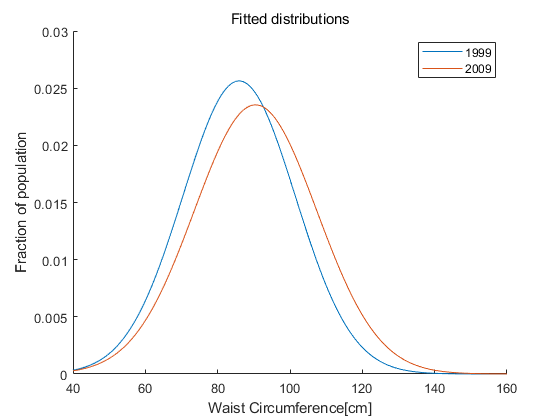

figure("Name","fig2");
hold on
plot(w,p1)
plot(w,p2) 
title("Fitted distributions")
legend("1999","2009")
xlabel("Waist Circumference[cm]")
ylabel("Fraction of population")
hold off